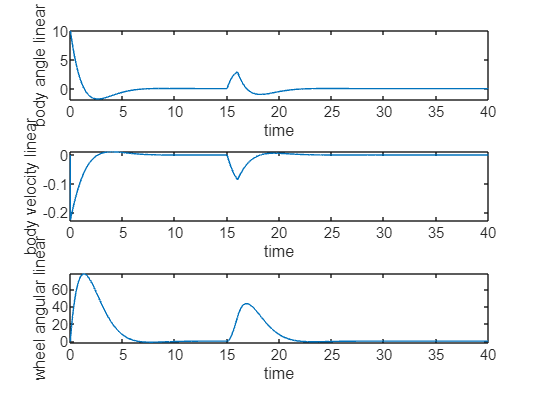

clc;
clear;
close all;

global l lb Mb Mw Ib Iw Cb Cw g Integral tp
l = 0.085;
lb = 0.075;
Mb = 0.419;
Mw = 0.204;
Ib = 0.00334;
Iw = 0.00057;
Cb = 0.00102;
Cw = 0.00005;
g = 9.81;
Integral = 0;
tp = 0;


tSpan = [0 40];
X0 = [pi/18 0 0 0];
[t,X]=ode45(@(t,x) lin_sysdyn(t,x), tSpan, X0);

subplot(3,1,1)
plot(t,X(:,1)*180/pi);
ylabel('body angle linear')
xlabel('time')

subplot(3,1,2)
plot(t, X(:,3));
ylabel('body velocity linear')
xlabel('time')

subplot(3,1,3)
plot(t,X(:,4));
ylabel('wheel angular linear')
xlabel('time')


% Define the vertices of the 2D cube
vertices = [0 0; 1/sqrt(2) 1/sqrt(2); 0 sqrt(2); -1/sqrt(2) 1/sqrt(2)];

% Define the faces of the 2D cube
faces = [1 2 3 4];

% Create a figure
figure;

% Plot the initial 2D cube
h = patch('Vertices', vertices, 'Faces', faces, 'FaceColor', 'b');

% Set axis limits
axis([-2 2 0 2]);

% Set axis labels
xlabel('X');
ylabel('Y');

% Set aspect ratio
axis square;

% Arrays of rotation angles in degrees and corresponding time values
rotationAngles = X(:,1)*180/pi;  % Update with your desired angles
times = t;  % Update with your desired time values

% Start time of the simulation
startTime = tic;

% Create animation
i = 1;
while i <= length(times)
    elapsedTime = toc(startTime);
    if elapsedTime >= times(i)
        angle = rotationAngles(i);
        i = i + 1;
    end
    rotationMatrix = [cosd(angle) -sind(angle); sind(angle) cosd(angle)];
    verticesRotated = vertices * rotationMatrix;
    set(h, 'Vertices', verticesRotated);
    pause(0.00001)
end




global l lb Mb Mw Ib Iw Cb Cw g Integral tp
l = 0.085;
lb = 0.075;
Mb = 0.419;
Mw = 0.204;
Ib = 0.00334;
Iw = 0.00057;
Cb = 0.00102;
Cw = 0.00005;
g = 9.81;
Integral = 0;
tp = 0;


tSpan = [0 40];
X0 = [pi/18 0 0 0];
[t,X]=ode45(@(t,x) sysdyn(t,x), tSpan, X0);

subplot(3,1,1)
plot(t,X(:,1)*180/pi);
ylabel('body angle non-linear')
xlabel('time')

subplot(3,1,2)
plot(t, X(:,3));
ylabel('body velocity non-linear')
xlabel('time')

subplot(3,1,3)
plot(t,X(:,4));
ylabel('wheel angular non-linear')
xlabel('time')

vertices = [0 0; 1/sqrt(2) 1/sqrt(2); 0 sqrt(2); -1/sqrt(2) 1/sqrt(2)];

% Define the faces of the 2D cube
faces = [1 2 3 4];

% Create a figure
figure;

% Plot the initial 2D cube
h = patch('Vertices', vertices, 'Faces', faces, 'FaceColor', 'b');

% Set axis limits
axis([-2 2 0 2]);

% Set axis labels
xlabel('X');
ylabel('Y');

% Set aspect ratio
axis square;

% Arrays of rotation angles in degrees and corresponding time values
rotationAngles = X(:,1)*180/pi;  % Update with your desired angles
times = t;  % Update with your desired time values

% Start time of the simulation
startTime = tic;

% Create animation
i = 1;
while i <= length(times)
    elapsedTime = toc(startTime);
    if elapsedTime >= times(i)
        angle = rotationAngles(i);
        i = i + 1;
    end
    rotationMatrix = [cosd(angle) -sind(angle); sind(angle) cosd(angle)];
    verticesRotated = vertices * rotationMatrix;
    set(h, 'Vertices', verticesRotated);
    pause(0.00001)
end

global l lb Mb Mw Ib Iw Cb Cw g Integral tp K_lqr
l = 0.085;
lb = 0.075;
Mb = 0.419;
Mw = 0.204;
Ib = 0.00334;
Iw = 0.00057;
Cb = 0.00102;
Cw = 0.00005;
g = 9.81;
Integral = 0;
tp = 0;

A = [0 0 1 0; 0 0 0 1; (Mb*lb + Mw*l)*g/(Ib + Mw*l*l) 0 -Cb/(Ib + Mw*l*l) Cw/(Ib + Mw*l*l); -(Mb*lb + Mw*l)*g/(Ib+Mw*l*l) 0 Cb/(Ib+Mw*l*l) (Ib+ Iw+ Mw*l*l)*(-Cw)/(Iw*(Ib + Mw*l*l))]
B = [0; 0; -1/(Ib + Mw*l*l); (Ib+ Iw+ Mw*l*l)/(Iw*(Ib + Mw*l*l))]
Q = [10 0 0 0; 0 1 0 0; 0 0 10 0; 0 0 0 0.1];
%Q = [10e4 0 0 0; 0 1 0 0; 0 0 10e4 0; 0 0 0 1];
%Q = [10e-2 0 0 0; 0 1 0 0; 0 0 10e-2 0; 0 0 0 10e-8];
%R = 10e8;
%R = 0.001;
R = 500;

K_lqr = lqr(A,B,Q,R)

tSpan = [0 40];
X0 = [pi/8 0 0 0]
[t,X]=ode45(@(t,x) sysdyn_lqr(t,x), tSpan, X0);

subplot(3,1,1)
plot(t,X(:,1)*180/pi);
ylabel('body angle LQR')
xlabel('time')

subplot(3,1,2)
plot(t, X(:,3));
ylabel('body velocity LQR')
xlabel('time')

subplot(3,1,3)
plot(t,X(:,4));
ylabel('wheel angular LQR')
xlabel('time')

vertices = [0 0; 1/sqrt(2) 1/sqrt(2); 0 sqrt(2); -1/sqrt(2) 1/sqrt(2)];

% Define the faces of the 2D cube
faces = [1 2 3 4];

% Create a figure
figure;

% Plot the initial 2D cube
h = patch('Vertices', vertices, 'Faces', faces, 'FaceColor', 'b');

% Set axis limits
axis([-2 2 0 2]);

% Set axis labels
xlabel('X');
ylabel('Y');

% Set aspect ratio
axis square;

% Arrays of rotation angles in degrees and corresponding time values
rotationAngles = X(:,1)*180/pi;  % Update with your desired angles
times = t;  % Update with your desired time values

% Start time of the simulation
startTime = tic;

% Create animation
i = 1;
while i <= length(times)
    elapsedTime = toc(startTime);
    if elapsedTime >= times(i)
        angle = rotationAngles(i);
        i = i + 1;
    end
    rotationMatrix = [cosd(angle) -sind(angle); sind(angle) cosd(angle)];
    verticesRotated = vertices * rotationMatrix;
    set(h, 'Vertices', verticesRotated);
    pause(0.00001)
end

function dX = sysdyn(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g
   load = Load(t);
   %load = 0;
   x1 = X(1); %theta_b
   x2 = X(2); % theta_w
   x3 = X(3) + load; %theta_b_dot
   x4 = X(4); %theta_w_dot
   Torque = control(t,X);
   dX = zeros(4,1);
   dX(1) = x3;
   dX(2) = x4;
   dX(3) = ((Mb*lb + Mw*l)*g*sin(x1) - Torque - Cb*x3 + Cw*x4)/(Ib + Mw*l*l);
   dX(4) = ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x4))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*sin(x1) - Cb*x3)/(Ib+Mw*l*l);
end

function dX = lin_sysdyn(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g
   load = Load(t);
   %load = 0;
   x1 = X(1); %theta_b
   x2 = X(2); % theta_w
   x3 = X(3) + load; %theta_b_dot
   x4 = X(4); %theta_w_dot
   Torque = control(t,X);
   dX = zeros(4,1);
   dX(1) = x3;
   dX(2) = x4;
   dX(3) = ((Mb*lb + Mw*l)*g*x1 - Torque - Cb*x3 + Cw*x4)/(Ib + Mw*l*l);
   dX(4) = ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x4))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*x1 - Cb*x3)/(Ib+Mw*l*l);
end

function dX = sysdyn_lqr(t,X)
   global l lb Mb Mw Ib Iw Cb Cw g
   load = Load(t);
   x1 = X(1);
   x2 = X(2);
   x3 = X(3) + load;
   x4 = X(4);
   global K_lqr
   Torque = -K_lqr*X;
   dX = zeros(4,1);
   dX(1) = x3;
   dX(2) = x4;
   dX(3) = ((Mb*lb + Mw*l)*g*x1 - Torque - Cb*x3 + Cw*x4)/(Ib + Mw*l*l);
   dX(4) = ((Ib+ Iw+ Mw*l*l)*(Torque - Cw*x4))/(Iw*(Ib + Mw*l*l)) - ((Mb*lb + Mw*l)*g*x1 - Cb*x3)/(Ib+Mw*l*l);
end

function torque = control(t,X)
    kp = 20;
    ki = 10;
    kd = 15;
    des = 0;
    e = X(1) - des;
    de = X(3);
    global Integral tp
    Integral = (Integral+ki*e*(t-tp));
    tp = t;
    torque = kp*e + Integral +kd*de;
end

function load = Load(t)
    if t > 15 && t < 16
         load = 0.1;     
    else
        load = 0;
    end
end